global L d n dist
n = 6;
m = 8;
d = 3;
gamma = 1;
rng(3);

s = [1 1 2 2 3 3 4 5];
t = [2 4 3 5 4 6 5 6];
G = graph(s,t);
H = incidence(G)'*eye(6);
A12 = [1 0 0; 0 2 1; 0 1 2];
%A13 = [0 0 0; 0 1 0; 0 0 1];
A25 = eye(3); A34 = A25;
A14 = [2 2 0; 2 2 0; 0 0 1];
A36 = A14;
A23 = [2 0 0; 0 0 0; 0 0 1];
A56 = A23;
A45 = [0 0 0; 0 1 0; 0 0 2];

W = blkdiag(A12,A14,A23,A25,A34,A36,A45,A56);

Hbar = kron(H,eye(d));
L = Hbar'*W*Hbar;
v=eig(L);
lambda_min = min(v(v>0.0001))

lambda_min = 0.2450

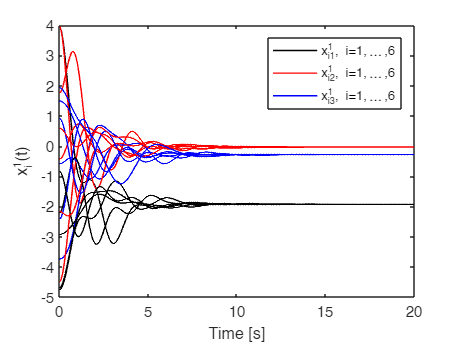

dist4 = 1; dist5 = 2; dist6 = [3; 4];
dist = [dist4; dist5; dist6];
z0 = 3*rand(4,1);
x0 = 10*(rand(d*n,1)-0.5);
r0 = [x0;zeros(d*n,1);z0];
options = odeset('RelTol',1e-7,'AbsTol',1e-6);

% Disturbance-observer based Matrix-weighted consensus
[t, r] = ode45(@dob_consensus, [0:0.01:20], r0, options);
r = r';
x1 = r(1:d*n,:); x2 = r(d*n+1:d*n*2,:);
z = r(d*n*2+1:end,:);
dhat = zeros(4,length(t));
for i=1:length(t)
    phi4 = [cos(3*t(i,1)); 1; 0];
    phi5 = [cos(3*t(i,1)) + 0.1*sin(5*t(i,1)); 0; 0.5*sin(5*t(i,1))];
    phi6 = [0.15*sin(5*t(i,1)+1) 0; 0.5*sin(5*t(i,1)) sin(3*t(i,1)); sin(2*t(i,1)) 0];
    dhat4 = z(1,i) + gamma*phi4'*x2(10:12,i);
    dhat5 = z(2,i) + gamma*phi5'*x2(13:15,i);
    dhat6 = z(3:4,i) + gamma*phi6'*x2(16:18,i);
    dhat(:,i) = [dhat4;dhat5;dhat6];
end


e = zeros(length(t),1);
for i=1:length(t)
    e(i,1) = norm(L*x(:,i));
end

figure
hold on;
for i=1:n
   plot(t,x1(3*i-2,:),'-k','LineWidth',1);
   plot(t,x1(3*i-1,:),'-r','LineWidth',1);
   plot(t,x1(3*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel 'x_i^1(t)';
box on;
legend({'x_{i1}^1, i=1,\ldots,6','x_{i2}^1, i=1,\ldots,6','x_{i3}^1, i=1,\ldots,6'},"NumColumns",1)

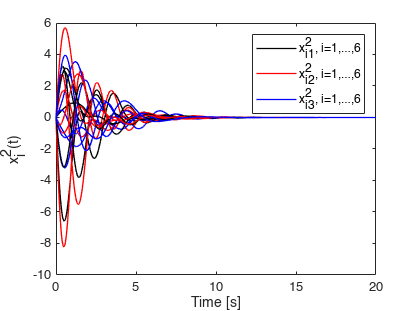


figure
hold on;
for i=1:n
   plot(t,x2(3*i-2,:),'-k','LineWidth',1);
   plot(t,x2(3*i-1,:),'-r','LineWidth',1);
   plot(t,x2(3*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel 'x_i^2(t)';
box on;
legend({'x_{i1}^2, i=1,\ldots,6','x_{i2}^2, i=1,\ldots,6','x_{i3}^2, i=1,\ldots,6'},"NumColumns",1)

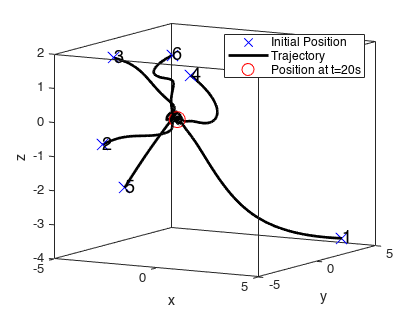


figure
hold on;
for i=1:n
   plot3(x(3*i-2,1),x(3*i-1,1),x(3*i,1),'xb','MarkerSize',12);
   plot3(x(3*i-2,:),x(3*i-1,:),x(3*i,:),'-k','LineWidth',2);
   plot3(x(3*i-2,end),x(3*i-1,end),x(3*i,end),'or','MarkerSize',12);
   text(x(3*i-2,1),x(3*i-1,1),x(3*i,1),num2str(i),"FontSize",14);
end
xlabel 'x'; ylabel 'y'; zlabel 'z';
ax = gca;
ax.BoxStyle = 'full';
box on
legend({'Initial Position','Trajectory','Position at t=20s'}, "NumColumns", 1)
view(30,10)

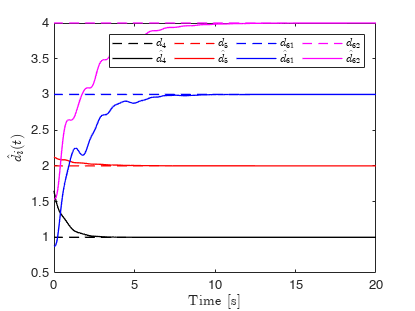


figure
hold on;
plot(t,dist(1,1)*ones(length(t),1),'--k','LineWidth',1);
plot(t,dhat(1,:),'-k','LineWidth',1);
plot(t,dist(2,1)*ones(length(t),1),'--r','LineWidth',1);
plot(t,dhat(2,:),'-r','LineWidth',1);
plot(t,dist(3,1)*ones(length(t),1),'--b','LineWidth',1);
plot(t,dhat(3,:),'-b','LineWidth',1);
plot(t,dist(4,1)*ones(length(t),1),'--m','LineWidth',1);
plot(t,dhat(4,:),'-m','LineWidth',1);
xlabel('Time [s]','Interpreter','latex'); 
ylabel('$\hat{d}_i(t)$','Interpreter','latex');
box on;
legend({'$d_4$','$\hat{d}_4$','$d_5$','$\hat{d}_5$',...
        '$d_{61}$','$\hat{d}_{61}$','$d_{62}$','$\hat{d}_{62}$'},...
        "NumColumns", 4, 'interpreter', 'latex');

function dx = dob_consensus(t,r)
    global L dist d n
    gamma = 1;
    x1 = r(1:d*n,:);
    x2 = r(d*n+1:2*d*n,:);
    z =  r(2*d*n+1:end,:);
    
    uc = -L*x1-x2;
    phi4 = [cos(3*t); 1; 0];
    phi5 = [cos(3*t) + 0.1*sin(5*t); 0; 0.5*sin(5*t)];
    phi6 = [0.15*sin(5*t+1) 0; 0.5*sin(5*t) sin(3*t); sin(2*t) 0];
    dhat4 = z(1,1) + gamma*phi4'*x2(10:12,1);
    dhat5 = z(2,1) + gamma*phi5'*x2(13:15,1);
    dhat6 = z(3:4,1)+gamma*phi6'*x2(16:18,1);
    
    u_err = [zeros(9,1); phi4*(dist(1)-dhat4); phi5*(dist(2,1)-dhat5); phi6*(dist(3:4,1)-dhat6)];
    dz4 = -gamma*phi4'*uc(10:12,1) - gamma*[-3*sin(3*t); 0; 0]'*x2(10:12,1);
    dz5 = -gamma*phi5'*uc(13:15,1) - gamma*[-3*sin(3*t)+0.5*cos(5*t); 0; 2.5*cos(5*t)]'*x2(13:15,1);
    dz6 = -gamma*phi6'*uc(16:18,1) - gamma*[0.75*cos(5*t+1) 0; 2.5*cos(5*t) 3*cos(3*t); 2*cos(2*t) 0]'*x2(16:18,1);
    dz = [dz4;dz5;dz6];
    dx = [x2; uc + u_err; dz];
end
